[data,fs]=audioread("s3.wav");

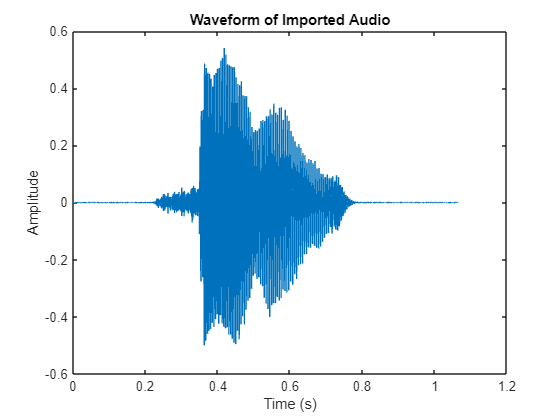

t = (0:length(data)-1)/fs;   % Time axis
plot(t, data);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of Imported Audio');

frame_length = 512;
overlap=0.5

overlap = 0.5000

frames=buffer(data,frame_length,round(overlap*frame_length),'nodelay');
frames

frames =     0.0005   -0.0005   -0.0010   -0.0005   -0.0005   -0.0005         0   -0.0005   -0.0005   -0.0005         0         0   -0.0122   -0.0015    0.0093   -0.0357    0.0063   -0.0122    0.3038   -0.3307   -0.1382   -0.0738    0.1104   -0.0513    0.1651   -0.0147   -0.0640    0.0044   -0.0098    0.0352    0.0591   -0.2134   -0.0034    0.0405    0.0449   -0.0601   -0.0552   -0.0191   -0.0010   -0.0020    0.0005         0         0   -0.0005         0         0   -0.0010         0    0.0005   -0.0010
    0.0005   -0.0010   -0.0015   -0.0005   -0.0005   -0.0005    0.0005   -0.0005   -0.0005   -0.0015         0   -0.0005    0.0107   -0.0064   -0.0030    0.0400    0.0083    0.0200    0.2598   -0.3233   -0.1505   -0.0518    0.3106   -0.0215    0.1402   -0.0323   -0.0601    0.0098   -0.0142    0.0186    0.0596   -0.1856   -0.0054    0.0337    0.0645   -0.0367   -0.0391   -0.0196   -0.0005   -0.0010    0.0005   -0.0005   -0.0010   -0.0010         0         0   -0.0005   -0.0005    0.0005

windowed_frames=apply_window(frames);

Windowing applied:
  Num frames:     51
  Frame length:   512
  Window type:    Hamming (periodic)
  Window min:     0.0800
  Window max:     1.0000
  Output size:    512 × 51


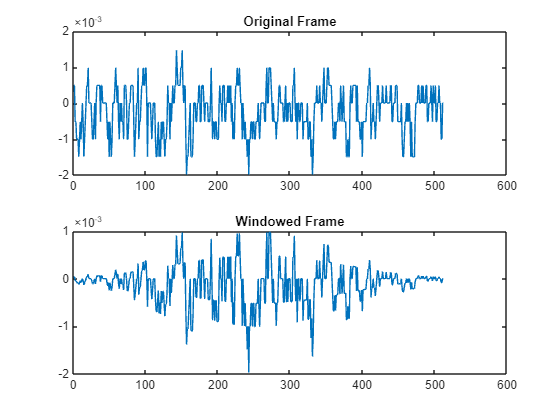

frameIdx = 1;
subplot(2,1,1);
plot(frames(:, frameIdx));
title('Original Frame');

subplot(2,1,2);
plot(windowed_frames(:, frameIdx));
title('Windowed Frame');

[frame_length_windowed,number_of_frames]=size(windowed_frames);
frame_length_windowed

frame_length_windowed = 512

number_of_frames

number_of_frames = 51

FFT_mat=zeros(frame_length_windowed,number_of_frames);
for i=1:number_of_frames
    FFT_mat(:,i)=myFFT(windowed_frames(:,i));
end
FFT_mat

FFT_mat =   -0.0619 + 0.0000i  -0.0637 + 0.0000i  -0.0651 + 0.0000i  -0.0653 + 0.0000i  -0.0595 + 0.0000i  -0.0627 + 0.0000i  -0.0643 + 0.0000i  -0.0630 + 0.0000i  -0.0629 + 0.0000i  -0.0654 + 0.0000i  -0.0627 + 0.0000i  -0.0596 + 0.0000i  -0.0654 + 0.0000i  -0.0587 + 0.0000i  -0.0630 + 0.0000i  -0.0510 + 0.0000i  -0.1126 + 0.0000i  -0.0976 + 0.0000i  -0.0424 + 0.0000i  -0.0382 + 0.0000i  -0.3745 + 0.0000i  -0.1900 + 0.0000i   0.2900 + 0.0000i   0.0654 + 0.0000i  -0.0457 + 0.0000i  -0.1429 + 0.0000i  -0.0746 + 0.0000i  -0.1562 + 0.0000i  -0.1414 + 0.0000i  -0.1779 + 0.0000i   0.0259 + 0.0000i   0.0498 + 0.0000i  -0.1647 + 0.0000i  -0.1022 + 0.0000i  -0.0163 + 0.0000i   0.0047 + 0.0000i  -0.0011 + 0.0000i  -0.0599 + 0.0000i  -0.0742 + 0.0000i  -0.0684 + 0.0000i  -0.0650 + 0.0000i  -0.0654 + 0.0000i  -0.0697 + 0.0000i  -0.0618 + 0.0000i  -0.0638 + 0.0000i  -0.0674 + 0.0000i  -0.0678 + 0.0000i  -0.0656 + 0.0000i  -0.0754 + 0.0000i  -0.0602 + 0.0000i
   0.0269 + 0.0006i   0.0273 - 0.0014i 

FFT_mat_abs=abs(FFT_mat)

FFT_mat_abs =     0.0619    0.0637    0.0651    0.0653    0.0595    0.0627    0.0643    0.0630    0.0629    0.0654    0.0627    0.0596    0.0654    0.0587    0.0630    0.0510    0.1126    0.0976    0.0424    0.0382    0.3745    0.1900    0.2900    0.0654    0.0457    0.1429    0.0746    0.1562    0.1414    0.1779    0.0259    0.0498    0.1647    0.1022    0.0163    0.0047    0.0011    0.0599    0.0742    0.0684    0.0650    0.0654    0.0697    0.0618    0.0638    0.0674    0.0678    0.0656    0.0754    0.0602
    0.0269    0.0273    0.0263    0.0297    0.0253    0.0277    0.0277    0.0265    0.0263    0.0279    0.0286    0.0257    0.0287    0.0267    0.0299    0.0502    0.0518    0.1307    0.0447    0.1050    0.2195    0.1102    0.3588    0.1289    0.0301    0.0594    0.0171    0.0941    0.1041    0.0911    0.1089    0.1076    0.0777    0.0881    0.0466    0.0718    0.0543    0.0379    0.0347    0.0315    0.0330    0.0287    0.0363    0.0264    0.0298    0.0346    0.0323    0.0292    0

FFT_mat_power=FFT_mat_abs(1:(frame_length/2)+1,:).^2

FFT_mat_power = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

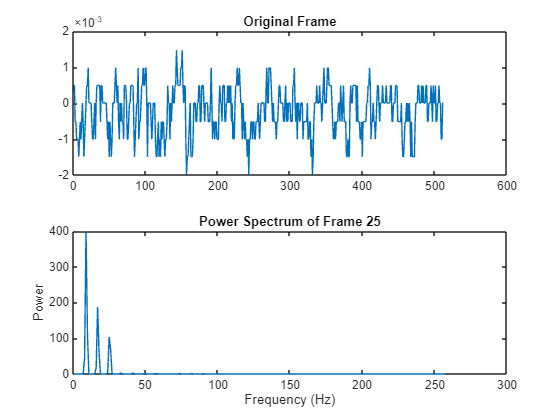

frameIdx = 25;   % pick a frame
plot(FFT_mat_power(:, frameIdx));
xlabel('Frequency (Hz)');
ylabel('Power');
title(sprintf('Power Spectrum of Frame %d', frameIdx));

Num_of_Mel_filters=20;
Melbank_filter=MelBank(fs,frame_length,Num_of_Mel_filters)

Melbank_filter =          0    0.3333    0.6667    1.0000    0.7500    0.5000    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.2500    0.5000    0.7500    1.0000    0.7500    0.5000    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Melbank_filtered_FFT=Melbank_filter*FFT_mat_power

Melbank_filtered_FFT = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002    0.0000    0.0000    0.0003    0.0001    0.0004    0.0001    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0009    0.0007    0.0005    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1070    0.4375    0.5136    0.5855    0.6265    0.6270    0.5919    0.4805    0.3986    0.4079    0.4099    0.3953    0.3263    0.2576    0.1832    0.1298    0.0948    0.0855    0.0976    0.0793    0.0118    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

% Plot as an image
imagesc(Melbank_filtered_FFT);

% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Mel Filter Index');
title('Mel Spectrogram (Energy in dB)');
colorbar;

R = corrcoef(Melbank_filtered_FFT);   % correlation across frames
R

R =     1.0000    0.6349    0.8318    0.2622   -0.2246    0.0016   -0.0896   -0.1878    0.3566    0.1316   -0.1582   -0.1646   -0.1871   -0.2017   -0.1788   -0.3263    0.7765    0.3721    0.6443    0.8112    0.8143    0.8291    0.8104    0.7726    0.7237    0.7168    0.7029    0.6748    0.6341    0.6130    0.6068    0.5965    0.5969    0.5952    0.5998    0.5568    0.5160    0.6105    0.6131    0.7638    0.6559    0.6487    0.5446    0.4206    0.2564    0.6730    0.6454    0.4796    0.3102    0.6713
    0.6349    1.0000    0.7575    0.4178   -0.0577    0.2320    0.0758   -0.0477    0.5240    0.0856   -0.0856   -0.0922   -0.1096   -0.1213   -0.1038   -0.2187    0.3293    0.1425    0.3746    0.6346    0.7180    0.7274    0.6896    0.6251    0.5725    0.6387    0.6634    0.6166    0.6112    0.5759    0.5545    0.5064    0.4521    0.4222    0.5191    0.5311    0.5279    0.5362    0.6549    0.7753    0.4778    0.1324    0.0174   -0.0290    0.0787    0.1749    0.0616    0.2972    0.3404    0

imagesc(R);
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation Intensity Between Frames');

Apply Log

Log_applied_MelBank_filtered_FFT=apply_log(Melbank_filtered_FFT)

Log_applied_MelBank_filtered_FFT =    -7.8807   -8.1317   -8.2208   -7.7540   -7.7969   -7.4901   -7.6520   -7.4774   -7.5154   -8.0082   -7.5738   -7.9798   -7.6745   -7.9009   -7.3269   -5.3229   -1.7439   -1.6105   -4.1627   -3.8519   -1.3509   -2.6038   -0.9583   -2.8133   -3.5260   -4.3820   -3.1757   -2.2013   -1.1925   -0.5920   -0.1478   -0.3253   -0.7668   -1.2808   -2.1098   -3.2039   -4.1149   -5.5265   -6.0552   -6.8561   -7.1110   -7.9442   -7.1973   -7.4893   -7.4587   -7.6096   -7.3991   -7.0534   -7.0615   -7.8404
   -6.1516   -6.3899   -7.1907   -6.4519   -6.8647   -6.7602   -7.2539   -7.2401   -6.6957   -6.9495   -6.0836   -7.1507   -7.8315   -7.2535   -7.3190   -4.2868    4.6728    6.0811    6.2414    6.3724    6.4402    6.4409    6.3833    6.1747    5.9880    6.0111    6.0159    5.9798    5.7877    5.5516    5.2107    4.8659    4.5518    4.4480    4.5806    4.3738    2.4677   -1.1223   -4.5467   -5.6284   -5.9406   -7.1140   -7.6789   -7.5114   -7.0287   -6.8729   -

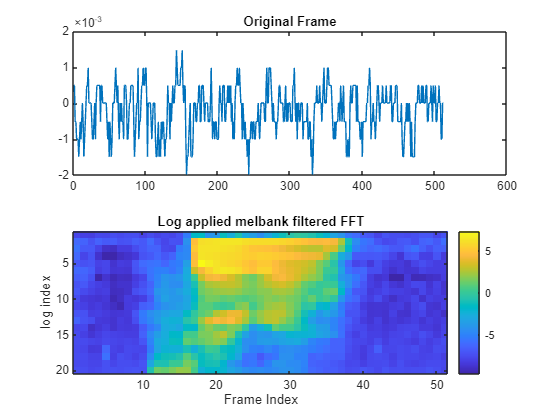

imagesc(Log_applied_MelBank_filtered_FFT);
colorbar;
xlabel('Frame Index');
ylabel('log index');
title('Log applied melbank filtered FFT');

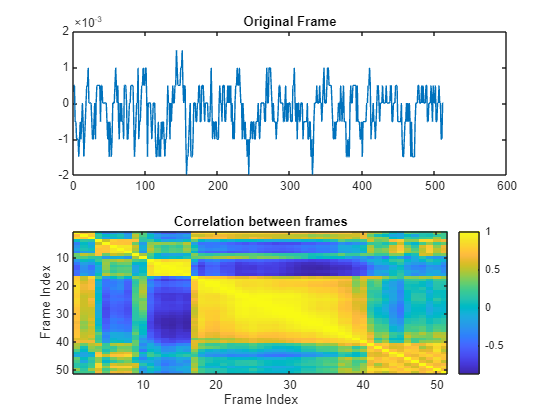

imagesc(corrcoef(Log_applied_MelBank_filtered_FFT));
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation between frames');

Apply Fourier Cosine transform

size(Log_applied_MelBank_filtered_FFT)

ans =     20    51


MFC_coefficients=apply_dct(Log_applied_MelBank_filtered_FFT,13)

MFC_coefficients =   -37.4905   -2.8202  -16.8968    2.9348    3.2021   -1.3275    4.7171   -0.6993   -4.7243   -0.3314    0.8669    0.3050    0.1908
  -11.1546   -2.9811  -38.4587    3.6105   10.5484    2.8260    8.0784   -5.9814   -5.5847   -0.0843   -0.2342    4.9166    3.3874
  -14.6652   -3.5892  -36.5426    0.0343    8.8267    5.0701    7.9021   -4.0344   -4.8779    1.4568    0.2828    5.6264    4.2065
  -17.5562   -1.3457  -40.1101   -0.6521   10.3436    2.7069    7.4179   -0.7016   -5.5540    1.3557    1.9142    3.4485    3.9827
  -18.9863    3.1894  -38.1339   -3.4934   10.4391    2.2043    6.6432   -1.0077   -6.0949    0.4361    1.8223    3.1971    3.9950
  -18.5477    3.0479  -38.0827   -1.8565   10.2970    2.9546    5.5434   -1.4454   -3.4444    1.2756    2.7398    2.6447    2.1616
  -24.5116    2.3979  -35.0865    0.0436    6.2964    0.0141    7.4798    1.1105   -2.2502    0.0920    3.3069    3.3326   -0.0497
  -25.5259    1.0025  -31.5764    0.1496    6.0104   -0.0714    

delta_MFCC=delta(MFC_coefficients)

delta_MFCC =     7.1987   -0.1699   -6.0853   -0.5125    1.8595    1.6949    0.9731   -1.1952   -0.1168    0.3824   -0.2269    1.5254    1.1228
    6.2694    0.2180   -6.6072   -1.0074    1.9908    1.4466    0.8587   -0.3340   -0.1813    0.5162    0.1511    1.1608    1.1599
    3.0607    1.3655   -4.4126   -1.7119    1.4269    0.6945    0.3192    0.4663   -0.2710    0.2975    0.4059    0.4316    0.8204
   -1.9107    1.8836   -0.0839   -1.4462    0.1110   -0.2609   -0.6329    1.2099    0.3064    0.1699    0.7488   -0.6973   -0.2663
   -2.0684    1.6368    0.4940   -0.1186   -0.5107   -0.9864   -0.2719    0.9546    0.7365   -0.2810    0.6874   -0.5391   -1.0333
   -2.1465    0.3905    2.0115    0.5140   -1.2809   -0.7747   -0.2778    0.3530    1.2180    0.0261   -0.0570   -0.1090   -1.3172
   -2.1781   -0.6026    2.2412    0.8742   -1.6492   -0.8976   -0.1718    0.3372    1.2137    0.5271   -0.5399   -0.1981   -0.9550
   -2.2896   -0.6291    2.2645    0.2913   -1.4015   -0.9817   -0.1480

delta_delta_MFCC=delta(delta_MFCC)

delta_delta_MFCC =    -0.9205    0.3459    0.2824   -0.2894   -0.0734   -0.2249   -0.1422    0.4184   -0.0373   -0.0036    0.1644   -0.2552   -0.0568
   -2.2357    0.5642    1.3676   -0.3067   -0.3930   -0.4912   -0.3866    0.6472    0.0692   -0.0510    0.2584   -0.5539   -0.3081
   -2.6714    0.5279    1.9682    0.0349   -0.6620   -0.7070   -0.3982    0.5843    0.2194   -0.1673    0.2426   -0.5987   -0.5739
   -2.1961    0.0616    2.2144    0.4636   -0.8481   -0.6124   -0.2864    0.1862    0.3806   -0.1559   -0.0135   -0.3510   -0.6808
   -1.0713   -0.5429    1.5403    0.7132   -0.7544   -0.3698   -0.0627   -0.1115    0.3881    0.0315   -0.2697   -0.0671   -0.4602
   -0.0867   -0.7265    0.6444    0.4468   -0.4163   -0.1353    0.1070   -0.2370    0.0968    0.1301   -0.4421    0.0795    0.0113
    0.0729   -0.4394    0.2536   -0.1072    0.0532    0.0574   -0.1013   -0.1216   -0.1593    0.1312   -0.3517   -0.0447    0.3498
    0.2999    0.1994   -0.3476   -0.5343    0.4841    0.1666   -

Final_feature_vector=[MFC_coefficients;delta_MFCC;delta_delta_MFCC]

Final_feature_vector =   -37.4905   -2.8202  -16.8968    2.9348    3.2021   -1.3275    4.7171   -0.6993   -4.7243   -0.3314    0.8669    0.3050    0.1908
  -11.1546   -2.9811  -38.4587    3.6105   10.5484    2.8260    8.0784   -5.9814   -5.5847   -0.0843   -0.2342    4.9166    3.3874
  -14.6652   -3.5892  -36.5426    0.0343    8.8267    5.0701    7.9021   -4.0344   -4.8779    1.4568    0.2828    5.6264    4.2065
  -17.5562   -1.3457  -40.1101   -0.6521   10.3436    2.7069    7.4179   -0.7016   -5.5540    1.3557    1.9142    3.4485    3.9827
  -18.9863    3.1894  -38.1339   -3.4934   10.4391    2.2043    6.6432   -1.0077   -6.0949    0.4361    1.8223    3.1971    3.9950
  -18.5477    3.0479  -38.0827   -1.8565   10.2970    2.9546    5.5434   -1.4454   -3.4444    1.2756    2.7398    2.6447    2.1616
  -24.5116    2.3979  -35.0865    0.0436    6.2964    0.0141    7.4798    1.1105   -2.2502    0.0920    3.3069    3.3326   -0.0497
  -25.5259    1.0025  -31.5764    0.1496    6.0104   -0.0714

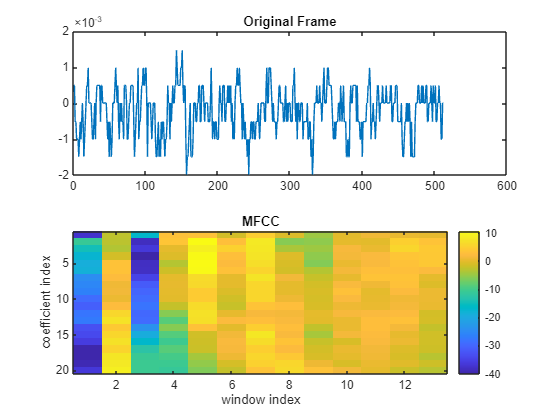

imagesc(MFC_coefficients);
colorbar;
xlabel('window index');
ylabel('coefficient index');
title('MFCC');

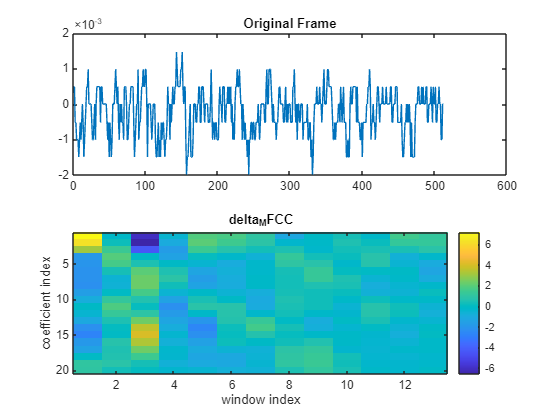

imagesc(delta_MFCC);
colorbar;
xlabel('window index');
ylabel('coefficient index');
title('delta_MFCC');

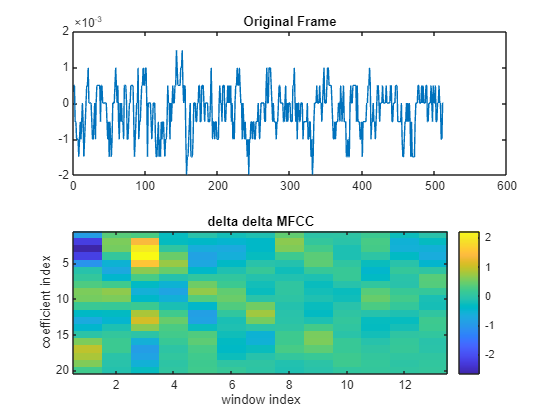

imagesc(delta_delta_MFCC);
colorbar;
xlabel('window index');
ylabel('coefficient index');
title('delta delta MFCC');

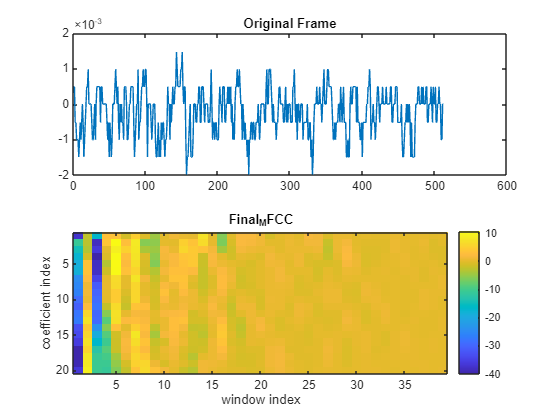

imagesc(Final_feature_vector);
colorbar;
xlabel('window index');
ylabel('coefficient index');
title('Final_MFCC');